# Juan Examples in LiveScript Matlab

this is normal after picking Title

% From insert tab can select Table of Contents - creates links to formatted text areas wi Hyperlinks

% Run refreshes TofC

% Section button to break up code - Neat

Each chapter is accompanied by a complete set of notes that you can find at [https://github.com/juanklopper/MATLAB...](https://www.youtube.com/redirect?event=video_description&redir_token=QUFFLUhqa3lmT0ZiVUNkT3FZNTUwcmFMMmJRc1ZfdFNIQXxBQ3Jtc0tuQm5LQzg3Q3d4eEdyX2ljMl9IR0lHS2N5T2NlcjVHb3g4SHUtaXFlQmJiWE9hWVBaVlA4bEVIeVJKb0dvTnZkTl9wTVJ1UGlycUU3QnlXM0FhbUVVSm1WY0ZHTmVTMFU3ckU3eE5vSUZxeVlJNm9qMA&q=https%3A%2F%2Fgithub.com%2Fjuanklopper%2FMATLAB4DataScience&v=2pVuWLZ-Ac8)  

There are six chapters in this course and you can find timestamps to each below. 

[00:05:26](https://www.youtube.com/watch?v=2pVuWLZ-Ac8&t=326s) Introducing MATLAB and Live Scripts

[01:02:35](https://www.youtube.com/watch?v=2pVuWLZ-Ac8&t=3755s) Vectors, matrices, and indexing 

[01:59:22](https://www.youtube.com/watch?v=2pVuWLZ-Ac8&t=7162s) Creating simulated data and exploratory data analysis 

[03:01:31](https://www.youtube.com/watch?v=2pVuWLZ-Ac8&t=10891s) Working with spreadsheets 

[03:33:12](https://www.youtube.com/watch?v=2pVuWLZ-Ac8&t=12792s) Data manipulation 

[04:06:19](https://www.youtube.com/watch?v=2pVuWLZ-Ac8&t=14779s) Common statistical tests

Video is [https://www.youtube.com/watch?v=2pVuWLZ-Ac8](https://www.youtube.com/watch?v=2pVuWLZ-Ac8)

the course says it is 5 hours and 12 minutes

## First section - basic calculations

% this is a comment

2+2

ans = 4

% subtraction
5-2

ans = 3

12/3/2

ans = 2

% buttons in right of this windows allow answer in code area

% PEMDAS order of Operations or left to right ...

## Second Section - Some Notes ...

% click striped bar to run a section chunk
% there is Run and Run Section buttons in Live Editor
clear variables % just clears vars - gone from WorkSpace
clear answers % just clears answers - in section

% has spell checking on

% Logarithm base e
log(-1)

ans = 0.0000 + 3.1416i


% Logarithm based 10
log2 (100)

ans = 6.6439

### Trigonometric functions

MATLAB can calculate all trigonometric and inverse trigonometric functions. Note that they keyword pi holds a numerical approximation of the irrational number π

% Sine function
sin(pi / 2)
% Cosine function
cos(pi / 2)
% Tangent function
tan(pi / 4)

## Computer variables

An object is assigned to a computer variable using the assignment operator, which is the equal symbol = in most languages. The assignment operator

assigns the object to its right to the computer variable to its left. Below we assign the number 17 (an object) to the computer variable x.

clearvars % Clear all variables in the workspace
% Assign the number 7 (an object) to the variable x
x = 17

% Call the variable x
x

## Container types

MATLAB has various containers for holding and representing data. An object is either empty or it holds values. 

In the next chapter we explore arrays in the form of vectors and matrices. Here, we list **seven** other container types.

### 1. Cell Arrays:

- Description: Cell arrays are data types with indexed data containers called cells, where each cell can contain any type of data. This includes arrays of different sizes and types.

 - Usage Example: C={1,'text',[2,3,4],magic(3)};

% Create the cell array C
C = {1,'text',[2,3,4],magic(3)} % Search the documentation (upper right corner) to look up the magic function

C = 1×4 cell array
    {[1]}    {'text'}    {[2 3 4]}    {3×3 double}


### 2. Structured Arrays (Structs):

 - Description: Structures are MATLAB data types that group related data using data containers called fields. Each field can contain any type of data. Fields are accessed using dot notation.

 - Usage Example: S.name = 'John'; S.age = 32; S.scores = [85, 90, 95];

S = struct with fields:

 name: 'John'

% Create the structure array S
S.name = 'John'

S = struct with fields:
    name: 'John'


S.age = 32

S = struct with fields:
    name: 'John'
     age: 32


S.scores = [85,90,95]

S = struct with fields:
      name: 'John'
       age: 32
    scores: [85 90 95]


### 3. Tables:

 - Description: Tables are data types suitable for storing column-oriented or tabular data of varying types. They are similar to data frames in R or

 Python's pandas. Tables allow for data manipulation and access using row and column names.

 - Usage Example: my_table = table([1;2;3],{'A';'B';'C'},[10.1;11.2;12.3],'VariableNames',{'ID','Label','Value'});

% Create the table my_table
my_table = table([1;2;3],{'A';'B';'C'},[10.1;11.2;12.3],'VariableNames',{'ID','Label','Value'})

my_table = 3×3 table
    ID    Label    Value
    __    _____    _____

    1     {'A'}    10.1 
    2     {'B'}    11.2 
    3     {'C'}    12.3 


### 4. Categorical Arrays:

 - Description: Categorical arrays are used for storing data that can take on a limited and fixed number of discrete categories. This is useful for nominal

or ordinal data.

 - Usage Example: my_cat_array = categorical({'red','green','blue','red','green'});

% Create the categorical array my_cat_array
my_cat_array = categorical({'red','green','blue','red','green'})

my_cat_array = 1×5 categorical array
     red      green      blue      red      green 


### 5. Containers.Map:

 - Description: Containers.Map is an associative array that allows for the storage of key-value pairs, where keys are unique identifiers. This is similar

to dictionaries in Python.

 - Usage Example: mapObj = containers.Map({'a', 'b', 'c'}, [1, 2, 3]);

% Create the containers.Map object mapObj
mapObj = containers.Map({'a','b','c'},[1,2,3])

mapObj =   Map with properties:

        Count: 3
      KeyType: char
    ValueType: double


% Call the keys
mapObj.keys

ans = 1×3 cell array
    {'a'}    {'b'}    {'c'}


% Call the values
mapObj.values

ans = 1×3 cell array
    {[1]}    {[2]}    {[3]}


### 6. Time Series:

- Description: Time series objects store time-stamped data, often used for financial, economic, and other time-dependent data.

 - Usage Example: datetime(2023,1,1):days(1):datetime(2023,1,10)

% Create 10 sequential dates from January 1, 2023 to January 10, 2023
datetime(2023,1,1):days(1):datetime(2023,1,10)

ans = 1×10 datetime array
   01-Jan-2023   02-Jan-2023   03-Jan-2023   04-Jan-2023   05-Jan-2023   06-Jan-2023   07-Jan-2023   08-Jan-2023   09-Jan-2023   10-Jan-2023


% Alternative notation using the caldays function
datetime(2023, 1, 1) + caldays(0:9)

ans = 1×10 datetime array
   01-Jan-2023   02-Jan-2023   03-Jan-2023   04-Jan-2023   05-Jan-2023   06-Jan-2023   07-Jan-2023   08-Jan-2023   09-Jan-2023   10-Jan-2023


### 7. String Arrays:

- Description: String arrays are containers for storing pieces of text data, where each element of the array is a string.

 - Usage Example: ["hello", "world", "MATLAB"];

% Create a string array
["hello","world","MATLAB"] % Must use double quotation marks

ans = 1×3 string array
    "hello"    "world"    "MATLAB"


These container types provide flexibility in handling various types of data, allowing for efficient data manipulation and organization in MATLAB

## 2| Vectors and Matrices

Data are often captured and saved in tabular format, such as in a spreadsheet. We have rows and columns of data. If each row of data is

that of a specific subject and if each column is of a defined variable, then a spreadsheet is said to be long-format tidy data. This is the

most convenient format and the format that we will consider here. The table below is long-format tidy data. Each row is a subject and each

column only contains data for a specific variable (and of a specific level of measurement).

### Vectors

Vectors are ordered lists of numbers. We can create both row and column vectors. Vector are typically assigned boldface lowercase letters.

Below we create the row vector . Note that any row vector has a single row and various columns. This is the size of a vector.

clear variables % Delete variables from the workspace
% Create the row vector u with elements 1, 2, and 3
u=[1 2 3] % Elements are separated by spaces by commas can also be used as in [1,2,3]

u =      1     2     3


The size function returns the number of rows and columns (as a row vector)

% Calculate the size of u
size(u) % Returns a row vector with elements indicating the number of rows and the number of columns

ans =      1     3


% Transpose of u is calculated using an apostrophe
u'

ans =      1
     2
     3


% Create the column vector v with elements 1, 2, and 3
v = [1;2;3] % Elements are separated by semicolons

v =      1
     2
     3


% Transpose of v
v'

ans =      1     2     3


% Add u and v
u+v'

ans =      2     4     6


% Scalar-vector multiplication
3*u

ans =      3     6     9


% Calculate the negative of vector v
-v

ans =     -1
    -2
    -3


% Calculate u minus the transpose of v
u-v'

ans =      0     0     0


% Create a row vector of the integers 1 through 10
1:10

ans =      1     2     3     4     5     6     7     8     9    10


% Add a step size of 2
1:2:11

ans =      1     3     5     7     9    11


% Create a row matrix of 10 numbers between 1 and 10
linspace(1,10,10)

ans =      1     2     3     4     5     6     7     8     9    10


### Matrices

Matrices are ordered lists of numbers arranged into rows and columns. We create the matrix below. Matrices are typically assigned to

uppercase letters.

clear variables
% Create the matrix A with 2 rows and three columns
A=[1 2 3;4 5 6]

A =      1     2     3
     4     5     6


% Creation by reshaping a vector
A=reshape([1 2 3 4 5 6 7 8 9],3,3)

A =      1     4     7
     2     5     8
     3     6     9


% Transpose of A
A'

ans =      1     2     3
     4     5     6
     7     8     9


% Matrix with three rows and four columns of 0's assigned to the variable A
A=zeros(3,4)

A =      0     0     0     0
     0     0     0     0
     0     0     0     0


% Matrix with three rows and four columns of 1's assigned to the variable A
A=ones(3,4)   

A =      1     1     1     1
     1     1     1     1
     1     1     1     1


% Create the identity matrix with 4 rows and columns assigned to the variable I
I=eye(4)

I =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


% Diagonal matrix with entries 3, 4, and 5 assigned to the variable A
diag([3 4 5])

ans =      3     0     0
     0     4     0
     0     0     5


% Use the square 4x4 matrix of ones and turn it into an upper triangular
% matrix assigned to the variable A
A=triu(ones(4))

A =      1     1     1     1
     0     1     1     1
     0     0     1     1
     0     0     0     1


% Use the square 4x4 matrix of ones and turn it into a lower triangular
% matrix assigned to the variable A
A=tril(ones(4))

A =      1     0     0     0
     1     1     0     0
     1     1     1     0
     1     1     1     1


% Create a new square matrix assigned to the variable A
A=[1 2 3;-4 5 2;3 2 1]

A =      1     2     3
    -4     5     2
     3     2     1


% Inverse of a square matrix
inv(A)

ans =    -0.0208   -0.0833    0.2292
   -0.2083    0.1667    0.2917
    0.4792   -0.0833   -0.2708


% Multiply A and the inverse of A
A*A'

ans =     14    12    10
    12    45     0
    10     0    14


% Determinant
det(A)

ans = -48.0000

Continue:

% Matrix-matrix addition (Matrices of similar sizes can be added. The
% operation is element wise).
A = eye(3);
B = ones(3);
A + B

ans =      2     1     1
     1     2     1
     1     1     2


% Scalar-matrix multiplication (Scalar-matrix multiplication is also element wise. Below, we multiply the matrix A by the scalar .
3 * A

ans =      3     0     0
     0     3     0
     0     0     3


Simple LaTeX example - ie, using Insert option -


$$$A=\left[\begin{array}{c} 1 & 2 & 3\\4 & 5 & 6\end{array} \right]$$$


% $A=\left[\begin{array}{c} 1 & 2 & 3\\4 & 5 & 6\end{array} \right]$


### Indexing

Every entry in a vector or matrix has an index (address).

clear variables
% Create a new 3 row, 4 column matrix assigned to the variable A
A = [3 4 2 8; 9 1 -3 7; -4 -5 0, 5]

A =      3     4     2     8
     9     1    -3     7
    -4    -5     0     5


% We use row-colu mn indexing to return the value of the element in row 2 and column 2 of A.
% Note the use of parentheses for indexing.
% Row 2, column 2
A(2,2)

ans = 1

% The colon symbol is shorthand that indicates that we want all the elements in the rows and or column. 
% Below we index row 2 and all the columns in that row. and the all the rows in column 3.

% All of row 2
A(2,:)

ans =      9     1    -3     7


% Next we index row 2 and columns 2 through 4 using a unit range object.
% Row 2, columns 2 through 4
A(2,2:4)

ans =      1    -3     7


% Finally we index the elements in row two for columns 2 and 4. The latter are passed as a row matrix.
% Row 2, columns 1 and 4
A(2,[1 4])

ans =      9     7


### Vector dot product

The dot product (or scalar inner product) of two vectors and both member of is defined as , shown below, where and

 are the elements of and respectively.

clear variables
% Create a vector u and a vector v
u=[1 2 3]

u =      1     2     3


v=[3 2 -1]

v =      3     2    -1


 % MATLAB will calculate the scalar dot product of two vectors with the same number of entries.
% Both can be row vectors and the first will be transposed automatically by MATLAB.
% Scalar dot product of u and v
dot(u,v)

ans = 4

% Create a weight-vector assigned to the variable w
w=repmat(1/5, 1, 5)

w =     0.2000    0.2000    0.2000    0.2000    0.2000


% Create a vector of subject ages assigned to the variable a
a=[33,56,53,39,49]

a =     33    56    53    39    49


% Mean age is .
% Dot product of weight vector and age vector
dot(w,a)

ans = 46.0000

% The mean function confirms that we have calculated the arithmetic mean.
% Mean of ages
mean(a)

ans = 46

### Matrix-vector multiplication

Matrix-vector multiplication is defined for matrices and . The result is a vector . Each element of the result

is the dot product of the rows of A and the vector .

clear variables
% Create a 4 row and 3 column matrix assigned to the variable A
A = [33,9,0.4;34,10,0.5;31,8,0.5;1,0,-1]

A =    33.0000    9.0000    0.4000
   34.0000   10.0000    0.5000
   31.0000    8.0000    0.5000
    1.0000         0   -1.0000


% Create a vector with 3 entries assigned to the variable v
v = [3;4;1]

v =      3
     4
     1


% The shape of the matrix and vector must be correct for matrix-vector
% multiplication
% A times v
mtimes(A,v)

ans =   135.4000
  142.5000
  125.5000
    2.0000


### Matrix-matrix multiplication

Matrix-matrix multiplication is defined for matrices and . The result is the matrix . Each element is the

dot product of the row of A and the column of B.

clear variables
% Create matrices A and B
A = [1 3 5; 2 4 7];
B = [-5 8 11; 3 9 21; 4 0 8];
% Matrix-matrix multiplication
A * B

ans =     24    35   114
    30    52   162


% In general matrix-matrix multiplication does not commute. We can always calculate or for any matrix.
% Calculate A times the transpose of A
A * A'

ans =     35    49
    49    69


% Calculate the transpose of A times A
A' * A

ans =      5    11    19
    11    25    43
    19    43    74


Note the difference in size of the two matrix-matrix products.

## 3| Simulated Data & Analysis

In this chapter we take a brief look at how to simulate random values, how to summarize them, and finally, how to visualize them. Once

we have access to clean and properly formatted data, our first tasks are always to summarize and visualize the data. This is termed

exploratory data analysis (EDA). We do this before applying any statistical tests. EDA gives us many insights into our data including

finding unexpected and also incorrect data.

clear variables
% Seed the pseudo-random number generator
rng(1,"twister");
% Random values from a discrete uniform distribution (of values 50 through
% 80) assigned to the variable ages
age = randi([50 80],5,1) % Create a 5 row column vector

age =     62
    72
    50
    59
    54


### Normal distribution

The normal distribution is described by a mean and a standard deviation. The curve of the normal distribution is the famous bell-shaped curve. We cannot assign a probability to each value in the sample space of a normal distribution as the values are real numbers.

Because of infinite decimal expansion we lose the ability to consider discrete elements in the sample space. Below we slect 5 values from the standard normal distribution (mean of 0 and standard deviation of 1).

% Seed the pseudo-random number generator
rng(1,"twister");
% Five values from the standard normal distribution assigned to the variable
% data
data = normrnd(0,1,[5,1])

data =    -0.6490
    1.1812
   -0.7585
   -1.1096
   -0.8456


### x2 distribution

The distribution is described by the degrees of freedom denoted by ν. Below, we select 5 values from a distribution with .v=2.

% Seed the pseudo-random number generator
rng(1,"twister");
% Five values from a chi-square distribution with two degrees of freedom assigned to the variable
% data
data = chi2rnd(2,[5,1])

data =     4.3418
    0.0669
    0.2182
    0.5998
    1.6464


### Summary statistics

The arithmetical mean of a sample of numerical data is calculated as shown below

% Sample mean
ages =[1 2 5 9]

ages =      1     2     5     9


mean(ages)

ans = 4.2500

% Sample median
median(ages)

ans = 3.5000

% Mode of the data
mode(data)

ans = 0.0669

### Measures of dispersion

**Variance**

% Sample variance
var(ages,0)

ans = 12.9167

#### Standard deviation

The units in which the variance is calculated is . In the case of our example, this is , which is non-nonsensical. As such, we take the square roots of the variance to calculate the standard deviation.

% Sample standard deviation
std(ages,0)

ans = 3.5940

#### Minimum and maximum

% Minimum
min(ages)

ans = 1

% Maximum
max(ages)

ans = 9

#### Range

The range is the difference between the maximum and the minimum values.

% Range
max(ages) - min(ages)

ans = 8

#### Quantiles

If the values of a numerical variable are written in ascending order, we can calculate any percentile value from to . A percentile of means that of values are less than and values are more than the calculated value. For this reason the median is the percentile value, also know as the second quartile value. The percentile value is the minimum of quartile value. The percentile is the first quartile value and the percentile is the third quartile value. Finally, the percentile is the fourth quartile value.

% First quartile
quantile(ages,0.25)

ans = 1.5000

% Third quartile
quantile(ages,0.75)

ans = 7

% IQR
iqr(ages)

ans = 5.5000

### Data visualization

**Visualizing distributions of numerical variables**

Histograms and box-and-whisker plots are good visualization of the distribution of numerical data. We start with a histogram of the frequency of values in the ages computer variable. Equally sized bins (intervals) are created and the frequency of values within each bin is displayed as the height of the bar for that interval. The bins are half-open intervals. Note that there are no gaps between the bars indicating the fact that the variable is continuous numerical.

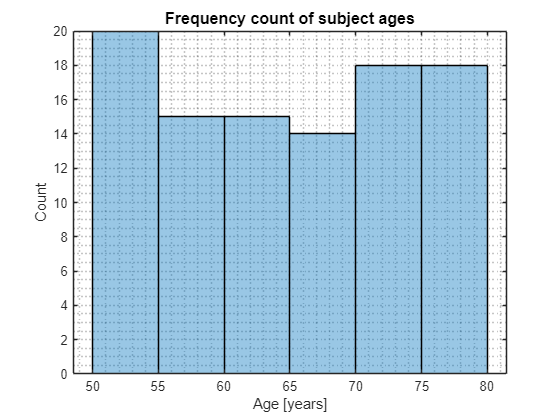

clear variables
% Seed the pseudo-random number generator
rng(1,"twister");
% Random values from a discrete uniform distribution (of values 50 through
% 80) assigned to the variable ages
ages = randi([50 80],100,1);
histogram(ages,10,"BinEdges",50:5:80,"FaceAlpha",0.4)
xlabel('Age [years]')
ylabel('Count')
title('Frequency count of subject ages',"FontSize",12)
grid minor

**A probability histogram divides the frequency of values in each interval by the sample size. This gives us the proportion of values in each interval.**

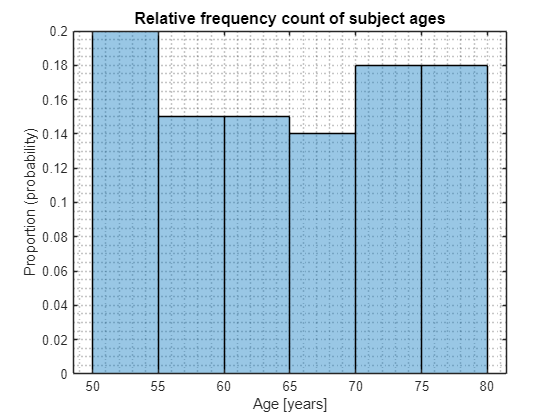

histogram(ages,10,"BinEdges",50:5:80,"FaceAlpha",0.4,"Normalization","probability")
xlabel('Age [years]')
ylabel('Proportion (probability)')
title('Relative frequency count of subject ages',"FontSize",12)
grid minor

**Dividing the proportion by the length of the interval gives us a probability density.**

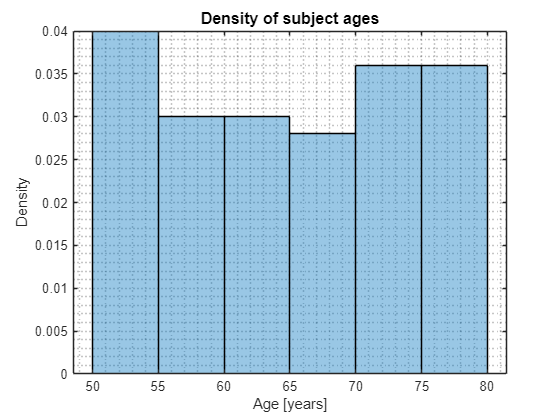

histogram(ages,10,"BinEdges",50:5:80,"FaceAlpha",0.4,"Normalization","pdf")
xlabel('Age [years]')
ylabel('Density')
title('Density of subject ages',"FontSize",12)
grid minor

**A cumulative distribution histogram adds the probabilities of sequential (left-to-right) intervals.**

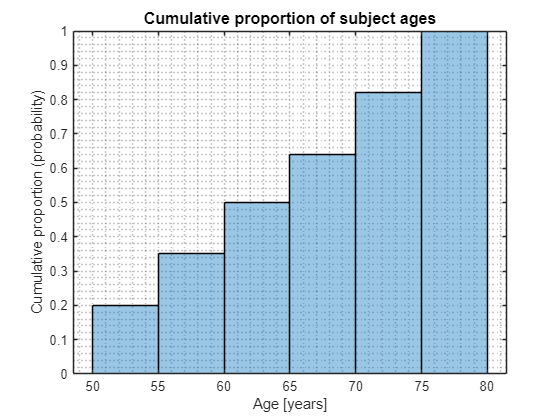

histogram(ages,10,"BinEdges",50:5:80,"FaceAlpha",0.4,"Normalization","cdf")
xlabel('Age [years]')
ylabel(['Cumulative proportion (probability)'])
title('Cumulative proportion of subject ages',"FontSize",12)
grid minor

**A box-and-whisker plot **show the median inside of a rectangle. The lower border of the rectangle is the first quartile and the upper border is the third quartile. If there are no suspected outliers then the lower fence (of the whiskers) is the minimum and the upper fence is the maximum. If there are suspected outliers the lower and upper fences will be at times the interquartile range below and above the first and third quartiles respectively. Suspected outliers will be indicated as individual markers outside the fences.

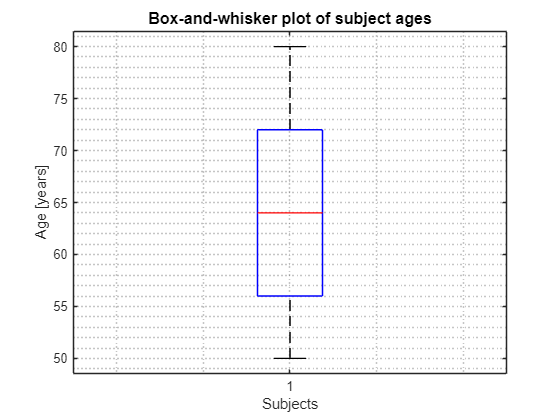

boxplot(ages)
xlabel('Subjects')
ylabel(['Age [years]'])
title('Box-and-whisker plot of subject ages',"FontSize",12)
grid minor

### Visualizing frequencies and relative frequencies of categorical variables

Bar plots show the frequency or relative frequency (proportion) of the classes (categories or levels) of a categorical variable or of discrete variables. Note that there are gaps between the bars indicating visually that the sample space elements of the variable do notform a continuum.

bar(["No","Yes"],[10,12])
xlabel('Classes')
ylabel(['Count'])
title('Frequency of classes',"FontSize",12)
ylim([0,13])
grid minor

### Visualizing the correlation between two numerical variables

A scatter plot visualizes the correlation between two numerical variables. One is placed on the x and one on the perpendicular yaxis.

Below, we visualize the linear relationship between the age and diastolic blood pressure values in our simulated data set.

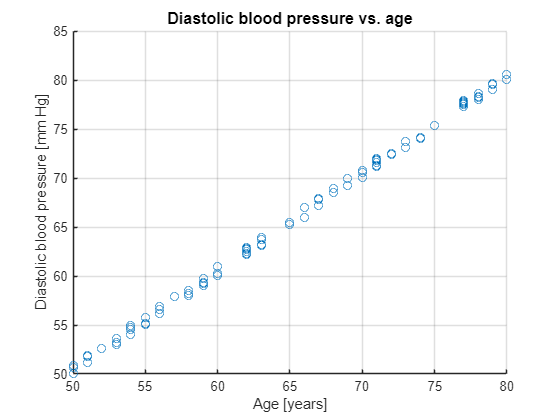

clear variables
% Seed the pseudo-random number generator
rng(1,"twister");
% Random values from a discrete uniform distribution (of values 50 through
% 80) assigned to the variable ages
ages = randi([50 80],100,1);
% Random values from a discrete uniform distribution (of values 60 through
% 90) assigned to the variable dbp
dbp = ages + rand(100,1);
scatter(ages,dbp)
xlabel('Age [years]')
ylabel(['Diastolic blood pressure [mm Hg]'])
title('Diastolic blood pressure vs. age',"FontSize",12)
grid on

### Definitions

The aim of data science is to extract information from data. Our goal is most often to learn about a population. We take a representative sample from a population. The sample data is analyzed and the results are used in inference, that is, we apply the result to others in the population. There are meany terms and symbols used in statistical analysis. Some of them are presented in this section

**Population**: The entire group of individuals or items that are the subject of a statistical study.

**Sample**: A subset of the population selected for analysis.

**Experiment**: A procedure carried out to test a hypothesis by observing outcomes under controlled conditions.

**Trial**: A single instance of conducting an experiment.

**Outcome**: The result of a single trial of an experiment.

**Sample Space**: The set of all possible outcomes of an experiment.

**Parameter**: A numerical characteristic of a population.

**Statistic**: A numerical characteristic of a sample used to estimate a population parameter.

**Frequency**: Count of the unique values in a data set.

**Relative frequency (proportion)**: The proportion of each unique element in a data set.

**Variable**: A generic term for the name of a specific measurement in each subject in a population or sample, often denoted by the symbol X (irrespective of the variable name).

**Random variable**: Each value in a variable, often denoted by , where i denotes an index.

**Observation**: A realization (actual value) that a random variable takes

**Independent and identically distributed** (i.i.d.) random variable: Condition often expected and assumed of a random variable.

Some of the terms and concepts above require more explanation. A collection of random variables is considered independent and identically distributed if each variable has the same probability distribution as the others and all are mutually independent. This means that each random variable in the set is generated under the same conditions and does not influence or depend on the values of the other random variables. As an example, we consider the age of a sample of subject. We might name the variable age in a spreadsheet.

For statistical analysis we name the variable X. We term the age of a random subject a random variable and use the symbol for that subject (where i is an index of values ). An observation is then the actual value usually denoted by and we write such as for the fourth subject. The concept of an i.i.d. random variable is fundamental in statistical theory and is often assumed in many statistical methods and models. In our age example, we will them assume that each is from the same distribution and each  is independent of all others random variables in the set.

There are two types of random variables. Discrete random variables are random variables that can take on a countable number of distinct values. Examples include the number of students in a class or the outcome of rolling a die. Each value is separate and distinct,

with gaps between possible values. Note that we are not considering levels of measurement when referring to random variables. In the case of a categorical variable we count the occurrences of each unique value in the sample space. Here our random variable is X, the frequency of a specific unique sample space element. Consider a binary variable which we might name smoke and which indicates if a subject is current smoking or not. We assign one of the two elements in the sample space of the variable (which we might denote as

Yes of No as the success class, for instance the Yes. The proportion of Yes values in the data set is then the random variable X).

Continuous random variables are random variables that can take on an infinite number of possible values within a given range.

Examples include the height of individuals or the time it takes to run a marathon. The values form a continuum, and any value within the range is possible.

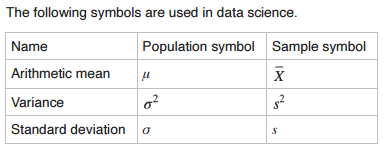

## 4 | WORKING WITH SPREADSHEETS

Script for importing data from the following spreadsheet:

 Workbook: /Users/juanheinklopper/Documents/MATLAB/MATLAB for Data Science/Data/heart.xlsx

** IN Matlab - Select the Home Tab --> Import data  - select heart.xlsx file --> change category type - Heart Disease to categorical -->  then Import Selection drop down -  as LiveScript. Save new File ....

## **5| **